% Objective function coefficients
f = [1; 1];

% Inequality constraints (Ax <= b)
A = [1, 2; -1, 2; 1, 5];
b = [3; 5; 12];

% Lower bounds on variables
lb = [0; 0];

% Solve the linear programming problem
[x, z] = linprog(f, [], [], A, b, lb);

% Display the results
fprintf('Optimal Solution:\n');
fprintf('x1 = %.2f\n', x(1));
fprintf('x2 = %.2f\n', x(2));
fprintf('Optimal Objective Value (z) = %.2f\n', z);





%https://ww2.mathworks.cn/help/optim/ug/linprog.html


% Objective function coefficients
f = [1; 1];

% Inequality constraints matrix A and right-hand side vector b
A = [1, -2; 1, 5];
b = [ -5; 12]; % b needs to be none-negative 

% Equality constraint matrix and right-hand side (empty in this case)
Aeq = [1,2];
beq = 3;

% Lower bounds and upper bounds for variables
lb = [0; 0];
ub = [];

% Solve the linear program using the simplex method
[x, z] = linprog(f, A, b, Aeq, beq, lb, ub);

找不到可行解。

Linprog 已停止，因为没有满足约束的点。




% Display the results
fprintf('Solution:\n');

Solution:


%fprintf('x1 = %.2f\n', x(1));
%fprintf('x2 = %.2f\n', x(2));
fprintf('Optimal objective value z = %.2f\n', z);

Optimal objective value z = 



3/2

ans = 1.5000


5/2

ans = 2.5000


12/5

ans = 2.4000


5*1.5 <= 12

ans = logical
   1


-2*1.5 <= -5

ans = logical
   0


2*1.5 == 3

ans = logical
   1




% Define the coefficients of the dual objective function
dual_c = [-3; 5; -12];  % Coefficients from the dual problem

% Define the coefficients matrix for the dual constraints
dual_A = [-1, 2, -5; -1, -2, 5];  % Coefficients from the dual problem

% Define the right-hand side of the dual constraints
dual_b = [-1; -1];  % Right-hand side values from the dual problem

% Define lower bounds for the dual variables
dual_lb = [0; 0; 0];

% Define upper bounds for the dual variables (no upper bounds)
dual_ub = [];

% Solve the dual linear program using the linprog function
[dual_y, dual_w] = linprog(dual_c, [], [], dual_A, dual_b, dual_lb, dual_ub);

找到最优解。




% Display the optimal dual solution and optimal dual objective value
fprintf('Optimal Dual Solution:\n');

Optimal Dual Solution:


fprintf('y1 = %.2f\n', dual_y(1));

y1 = 1.00


fprintf('y2 = %.2f\n', dual_y(2));

y2 = 0.00


fprintf('y3 = %.2f\n', dual_y(3));

y3 = 0.00


fprintf('Optimal Dual Objective Value (w) = %.2f\n', dual_w);

Optimal Dual Objective Value (w) = -3.00


A = [2 0 0;
     2 1 0;
     5 0 1
    ]
inv(A)






% Define the coefficients of the objective function to maximize
c = [-3; -1];  % Coefficients for x1 and x2

% Define the coefficients matrix for the inequality constraints
A = [4, 1; 5, 2];  % Coefficients for x1 and x2 in each constraint

% Define the right-hand side vector of the inequality constraints
b = [7; 10];

% Define lower bounds for the variables x1 and x2 (both are non-negative)
lb = [0; 0];

% Define upper bounds for the variables x1 and x2 (no upper bounds)
ub = [];

% Solve the linear program using the linprog function
[x, z] = linprog(c, [], [], A, b, lb, ub);

找到最优解。




% Display the optimal solution and optimal objective value
fprintf('Optimal Solution:\n');

Optimal Solution:


fprintf('x1 = %.2f\n', x(1));

x1 = 1.33


fprintf('x2 = %.2f\n', x(2));

x2 = 1.67


fprintf('Optimal Objective Value (z) = %.2f\n', -z);  % Negate the result to maximize

Optimal Objective Value (z) = 5.67




17/3

ans = 5.6667

4/3

ans = 1.3333

5/3

ans = 1.6667

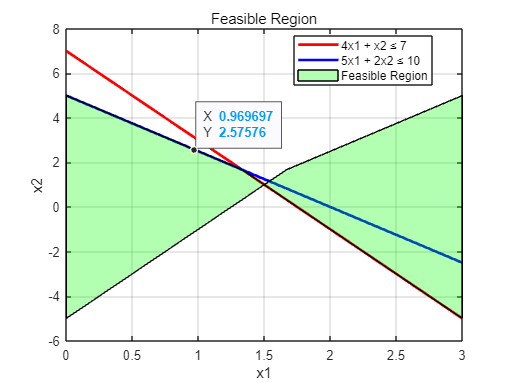

% Define the range of x1 values
x1 = linspace(0, 3, 100);  % Choose a range of x1 values

% Calculate corresponding x2 values for both constraints
x2_constraint1 = 7 - 4 * x1;
x2_constraint2 = 5 - 5/2 * x1;

% Plot the feasible region
figure;
plot(x1, x2_constraint1, 'r', 'LineWidth', 2);  % Red line for the first constraint
hold on;
plot(x1, x2_constraint2, 'b', 'LineWidth', 2);  % Blue line for the second constraint

% Fill the feasible region
fill([x1, fliplr(x1)], [min(x2_constraint1, x2_constraint2), min(x2_constraint1, x2_constraint2)], 'g', 'FaceAlpha', 0.3);
xlabel('x1');
ylabel('x2');
title('Feasible Region');
legend('4x1 + x2 ≤ 7', '5x1 + 2x2 ≤ 10', 'Feasible Region', 'Location', 'Best');
grid on;




0zzzzzzzzzzzzzzza

无效表达式。请检查缺失的乘法运算符、缺失或不对称的分隔符或者其他语法错误。要构造矩阵，请使用方括号而不是圆括号。

close all;
L1 = [2.5, 0;2.5, 4];
plot(L1(:,1),L1(:,2));hold on
text(2.1,3.5,'x_1=2.5','color','b');

L2 = [0, 3;4, 3];
plot(L2(:,1),L2(:,2));hold on
text(1.8,2.8,'x_2=3','color','b');

L3 = [0, 2;2, 4];
plot(L3(:,1),L3(:,2));hold on
text(1.5,3.4,'x_1-x_2=-2','color','b');

L4 = [0, 4;1, 3];
plot(L4(:,1),L4(:,2));hold on
text(2,2.1,'x_1+x_2=4','color','b');

x=[2.5 2.5 1]';%% Get the equation intersection points(extrem point)
y=[0 1.5 3]';
fill(x,y,'r')
xlabel('x_1')
ylabel('x_2')
axis([0 5 -0.2 4])

%%z1 = [0,2;2,1];
%%plot(z1(:,1),z1(:,2),'k--','Linewidth',2);hold on
%%text(1.5,1.5,'z1=4');

%%z2 = [1,9/4; 3,5/4];
%%plot(z2(:,1),z2(:,2),'k--','Linewidth',2);hold on
%%text(2,1.4,'z2=5.5');

%%z3 = [0.5,13/4;4,3/2];
%%plot(z3(:,1),z3(:,2),'k--','Linewidth',2);hold on
%%text(2.5,2,'z3=7');

alpha = [0,6;3,0];
plot(alpha(:,1),alpha(:,2),':','Linewidth',2);hold on
text(1,3.7,'alpha=6, 2x_1+x_2=6');

alpha2 = [0,5;3,-1];
plot(alpha2(:,1),alpha2(:,2),':','Linewidth',2);hold on
text(0.8,2.7,'alpha=5, 2x_1+x_2=5');

alpha3 = [3,0.5;0,6.5];
plot(alpha3(:,1),alpha3(:,2),':','Linewidth',2);hold on
text(2.6,1.5,'alpha=6.5, 2x_1+x_2=6.5');


alpha4 = [0,0;1,-2];
plot(alpha4(:,1),alpha4(:,2),':','Linewidth',2);hold on
text(0.3,0,'alpha=0, 2x_1+x_2=0');

%%alpha5 = [3,0.5;0,6.5];
%%plot(alpha4(:,1),alpha4(:,2),':','Linewidth',2);hold on
%%text(0.5,0.5,'alpha=0, 2x_1+x_2=0');





